% fc_pre_group_all_chan=[[1,3,4,76,88,3,54,6]    
% [2,54,3,656,8,9999,65,3]
% [5,34,3,6,77,4,234,9999]]

fc_pre_group_all_chan =            1           3           4          76          88           3          54           6
           2          54           3         656           8        9999          65           3
           5          34           3           6          77           4         234        9999



SAVE_DIR = "../saved_data";
save(sprintf("%s/fc_pre_group_all_chan.mat", SAVE_DIR), 'fc_pre_group_all_chan'); 

B = zeros(8760, size(A,2));

Unrecognized function or variable 'A'.

B(A(:,1),:) = A

B(B(:,1)==0,2:end) = 9999;
B(:,1) = 1:8760   % (Used 1:5 in my example below)

conn_mat
B = NaN(64, size(conn_mat, 2));
intersect = ismember(data_load.allart.channel, source_conn.label);
intersect_idx = find(intersect == 1)
B(intersect_idx, :) = conn_mat

C = NaN(size(B, 1), 64);
C(:, intersect_idx) = B

imagesc(C)

A = [1.77 -0.005 NaN -2.95; NaN 0.34 NaN 0.19; 0.34 NaN NaN 0.19]
M = mean(A,2,"omitnan")


% [p,h,stats] = signrank(fc_pre_group_avg, fc_post_group_avg, 'alpha', 0.05, )
function [corrected_pvals, significant_pairs, w_stat_vals] = wilcoxon_fdr(pre, post, alpha)
    % Inputs:
    % pre  - (64, 64, n) connectivity matrix for "pre" condition
    % post - (64, 64, n) connectivity matrix for "post" condition
    % alpha - significance level (default 0.05)
    
    % Ensure the matrices are symmetric (if applicable)
    assert(isequal(size(pre), size(post)), 'Pre and Post matrices must have the same dimensions.');
    [n_channels, ~, n_participants] = size(pre);
    
    % Initialize storage
    p_values = []; % Store p-values for all (i, j) pairs
    w_stats = [];
    % Iterate through upper triangle of matrix (including diagonal)
    for i = 1:n_channels
        for j = i:n_channels
            % Extract paired data across participants
            pre_values = squeeze(pre(i, j, :));  % Vector of size (n_participants, 1)
            post_values = squeeze(post(i, j, :)); % Vector of size (n_participants, 1)
            
            % disp("debug");
            % disp((pre_values));
            % disp((post_values));
            % disp(pre_values - post_values);
            % diffs = pre_values - post_values;
            % nonzero_diffs = sum(diffs ~= 0);
            % disp(nonzero_diffs);
            % disp(size(pre, 3)); % This should be the number of participants
            % disp("end debug");

            % Perform Wilcoxon signed-rank test
            try 
                [p,h,stats] = signrank(pre_values, post_values, 'tail', 'right'); % Two-tailed test --> 'tail', 'right' is checking whether pre-post > 0; ==> if yes, then there was a decrease
                % disp(stats);
                p_values = [p_values; p]; % Append p-value to the list
                w_stats = [w_stats; stats.signedrank];
            catch ME
                if ME.message == "No data remaining after removal of NaNs."
                    p = NaN;
                    p_values = [p_values; p];
                    w_stats = [w_stats; p];
                end
            end 
        end

    end
    disp(size(w_stats));
    disp(p_values);
    % Apply FDR correction
    % [fdr_corrected_pvals, rejected] = mafdr(p_values, 'BHFDR', true);
    fdr_corrected_pvals = mafdr(p_values, 'BHFDR', true);
    rejected = fdr_corrected_pvals < alpha; % Logical array for significant tests
    
    % Identify significant pairs
    significant_indices = find(rejected); % Indices of significant pairs
    corrected_pvals = fdr_corrected_pvals; % Return corrected p-values
    
    % Map indices back to (i, j) electrode pairs
    significant_pairs = [];
    w_stat_vals = zeros(n_channels, n_channels);
    count = 0;
    for i = 1:n_channels
        for j = i:n_channels
            count = count + 1;
            w_stat_vals(i, j) = w_stats(count);
            if ismember(count, significant_indices)
                significant_pairs = [significant_pairs; i, j]; % Append (i, j) pair
            end
        end
    end
end

function W_normalized = normalize_wilcoxon(W_matrix, n)
    % Inputs:
    % W_matrix - A 2x2 matrix containing Wilcoxon W-statistics
    % n - Number of paired samples
    
    % Step 1: Compute total rank sum
    R_total = n * (n + 1) / 2;
    
    % Step 2: Compute normalization factor
    normalization_factor = R_total / 2;
    
    % Step 3: Normalize each W-statistic
    W_normalized = (W_matrix - normalization_factor) / normalization_factor;
end



[corrected_pvals, significant_pairs, w_stat_vals] = wilcoxon_fdr(fc_pre_group_all_chan, fc_post_group_all_chan, 0.05)

        2080           1

    1.0000
    0.1875
    0.7656
    0.3125
    0.8906
    0.5938
    0.1484
    0.1562
    0.9688
    0.8750
    0.2480
    0.1914
    0.1914
    0.3262
    0.5771
    0.9805
    0.1250
    0.0488
    0.0039
    0.2734
    0.5000
    0.1250
    0.1504
    0.0547
    0.3125
    0.5000
    0.5625
    0.1562
    0.0391
    0.1484
    0.7188
    0.3438
    0.2344
    0.5938
    0.9033
    0.5000
    0.6875
    0.7812
    0.0977
    0.1875
    0.8125
    0.5625
    0.1562
    0.3711
    0.0654
    0.7520
    0.8750
    0.1797
    0.0137
    0.0820
    0.0137
    0.0020
    0.0547
    0.1094
    0.3262
    0.1094
    0.3438
    0.1250
    0.3125
    0.5000
    0.3438
    0.9727
    0.1250
    0.0234
    1.0000
    0.4197
    0.1484
    0.6289
    0.6562
    0.1026
    0.2274
    0.1914
    0.1562
    0.0765
    0.0324
    0.0079
    0.0250
    0.0925
    0.9137
    0.3129
    0.4249
    0.0015
    0.2244
    0.5781
    0.0159
    0.0065
    0.0051
    0.0133
    0.

corrected_pvals =     1.0000
    0.3539
    0.8453
    0.4682
    0.9389
    0.6973
    0.3152
    0.3152
    1.0000
    0.9267



significant_pairs =

     []



w_stat_vals =      0    37    10     7     5     7    21    12     2     2    29    25    25    27    26     4    33    37    44    23     1    27    32    30    10     2     5    12    31    21     8    17    19    13    15    11     4     7    28    20     9     5    12    21    43    17    10    31    49    35
     0     0    49    21    16    12    93    57    25    16    76   116   128   131   105    31    61    81   154    93    10   110   143   104    77    16    33    33   141    70    33    42    31    48   125    43    32    24    71    81    36    25    80   117   112    71    87   142   112    97
     0     0     0    15    13    10    70    51    13     6    39    68    71    67    37    14    29    35    52    59     8    69    69    53    56     9    15    25    68    29    14    29     7    26    32    35    25    10    35    49    12    17    42    63    59    23    47    64    54    54
     0     0     0     0     6    11    19    16     0     6    13    14    18     


% extend into full matrix:
% w_symmetric = w_stat_vals;
w_symmetric = triu(w_stat_vals) + triu(w_stat_vals, 1)';

disp('w_stat_vals:');

w_stat_vals:


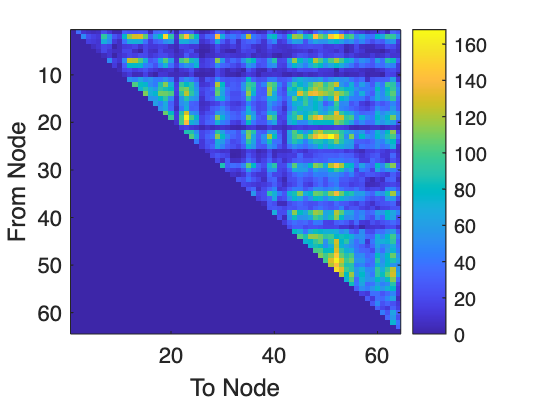

figure;imagesc(w_stat_vals);
xlabel('To Node');
ylabel('From Node');
% xticks(data_load.data_interp_avgref.label);
cbh = colorbar();


disp('w_symmetric:');

w_symmetric:


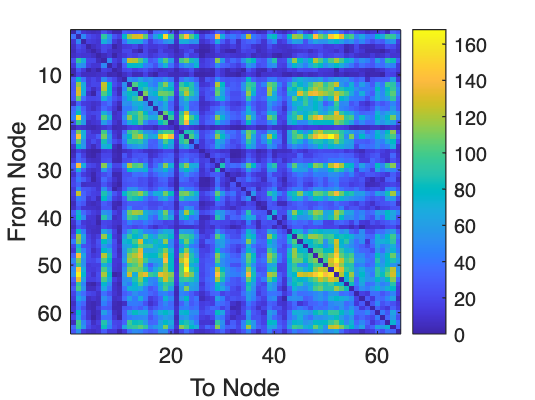

figure;imagesc(w_symmetric);
xlabel('To Node');
ylabel('From Node');
% xticks(data_load.data_interp_avgref.label);
cbh = colorbar();



% Normalize W-statistics
W_normalized = normalize_wilcoxon(w_symmetric, 19);

% Display result
disp('Normalized Wilcoxon W-statistics: (effect size - from Barnett et al., 2020)');

Normalized Wilcoxon W-statistics: (effect size - from Barnett et al., 2020)


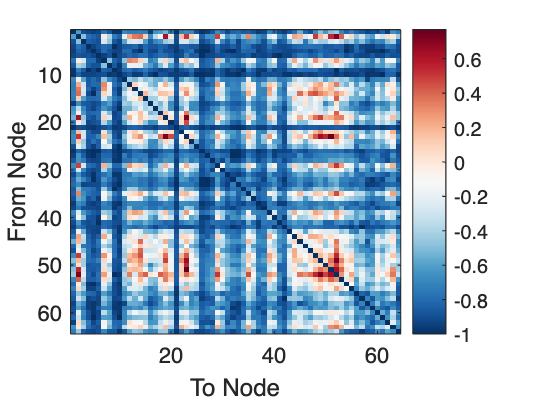

figure;imagesc(W_normalized);
xlabel('To Node');
ylabel('From Node');
% xticks(data_load.data_interp_avgref.label);
% cbh = colorbar();
N = 256; % number of colorsdd
% cmap = [linspace(0,1,N).' linspace(0,1,N).' ones(N,1)]; % decreasing R and G; B = 1
cmap = brewermap(N, '-RdBu');
cbh = colormap(cmap);
colorbar;

% topographic map (10:46pm)
% vector for topographic plot = 
% plot_topography(ALL_ELECTRODES, W_normalized, true, 'Acticap_standard_snap.mat', true, false, 1000);

cfg = [];
cfg.layout = '../Acticap_standard_snap.mat'; 
layout = ft_prepare_layout(cfg);

reading layout from file ../Acticap_standard_snap.mat
reading 'layout' from file '../Acticap_standard_snap.mat'
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB



connectivity_mean = mean(W_normalized, 2); % Mean of rows (averaging across all pairs for each electrode)

data = [];
data.label = layout.label(1:64,:);           % Electrode labels
data.avg = connectivity_mean';       % Connectivity values (1x64)
data.time = 1;                       % Dummy time point
data.dimord = 'chan_time';           % Specify data dimension

comments = 'freq=[8 13]'

comments = 'freq=[8 13]'


cfg = [];
cfg.layout = layout;                 % Use loaded layout
cfg.parameter = 'avg';               % Specify data parameter
cfg.zlim = [-1 1];
cfg.colorbar = 'yes';
cfg.comment = comments;
ft_topoplotTFR(cfg, data);

the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB


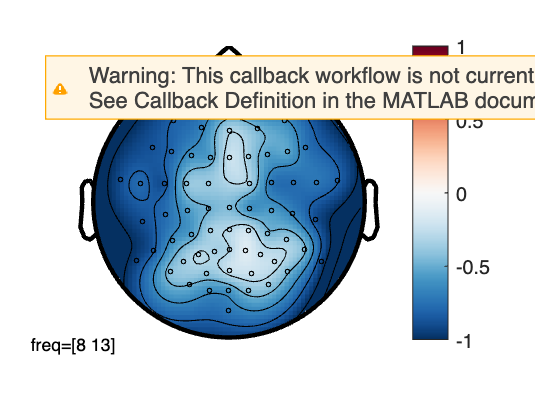

N = 256; % number of colorsdd
% cmap = [linspace(0,1,N).' linspace(0,1,N).' ones(N,1)]; % decreasing R and G; B = 1
cmap = brewermap(N, '-RdBu');
cbh = colormap(cmap);
colorbar;


% cfg                  = [];
% cfg.parameter        = 'cohspctrm';
% cfg.zlim             = [-1 1];
% cfg.refchannel       = 'all';
% cfg.layout           = 'Acticap_standard_snap.mat'; % 'easycapM11.mat'; % 'CTF151_helmet.mat';
% 
% test_source_conn = source_conn;
% test_source_conn.cohspctrm = W_normalized;
% figure; ft_topoplotER(cfg, test_source_conn)
% cbh = colorbar();


% 
% cfg = []; 
% cfg.layout = 'Acticap_standard_snap.mat'; 
% cfg.projection = 'polar';
% [layout, cfg] = ft_prepare_layout(cfg);
% 
% layout_topo = zeros(64, 3);
% layout_topo(:, 1) = str2double(ALL_ELECTRODES);
% layout_topo(:, 2:3) = layout.pos(1:64, :);
% layout_table = array2table(layout_topo, 'VariableNames',{'labels','radius','theta'})
% plot_topography(ALL_ELECTRODES, W_normalized, true, layout_table, true, false, 1000);

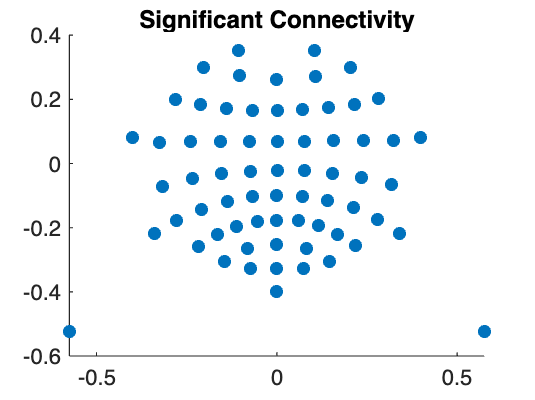

% Example: Draw significant connections on top of a scalp map
% significant_pairs = W_normalized > 0.3; % Threshold connections

indices = zeros(64, 64);
for i = 1:length(significant_pairs)
    row = significant_pairs(i, 1);
    col = significant_pairs(i, 2);
    indices(row, col) = 1;
    indices(col, row) = 1;
end

figure;
hold on;

% Plot electrode locations
scatter(layout.pos(:, 1), layout.pos(:, 2), 'filled');
for i = 1:64
    for j = 1:64
        if indices(i, j) % If the connection is significant
            plot([layout.pos(i, 1) layout.pos(j, 1)], ...
                 [layout.pos(i, 2) layout.pos(j, 2)], ...
                 'k-', 'LineWidth', 0.5); % Draw a line between electrodes
        end
    end
end
title('Significant Connectivity');
hold off;

% Desired new order of electrodes
newOrder = electrode_idx_by_region;
% Reorder the matrix
reorderedMatrix = W_normalized(newOrder, newOrder);
% (Optional) Reorder labels
reorderedLabels = electrodes_by_region;

disp('Reordered Matrix:');

Reordered Matrix:


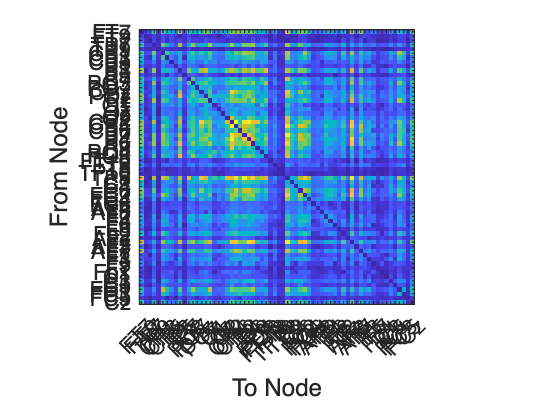

figure;imagesc(reorderedMatrix);
xlabel('To Node');
ylabel('From Node');
axis square; % Makes the axes equal in size for a square plot
% Add labels to rows and columns
xticks(1:length(reorderedLabels)); % Set x-axis ticks at integer positions
yticks(1:length(reorderedLabels)); % Set y-axis ticks at integer positions
xticklabels(reorderedLabels); % Set x-axis labels
yticklabels(reorderedLabels); % Set y-axis labels
% Rotate x-axis labels if needed
xtickangle(45); % Rotates x-axis labels by 45 degrees for better readability

% xticklabels(reorderedLabels);
% cbh = colorbar();

% Find rows and columns with NaN values
nan_rows = all(isnan(reorderedMatrix), 2); % Rows with NaN
nan_cols = all(isnan(reorderedMatrix), 1); % Columns with NaN
% Remove rows and columns with NaN values
B = reorderedMatrix(~nan_rows, ~nan_cols);
disp('Reordered Matrix:');

Reordered Matrix:


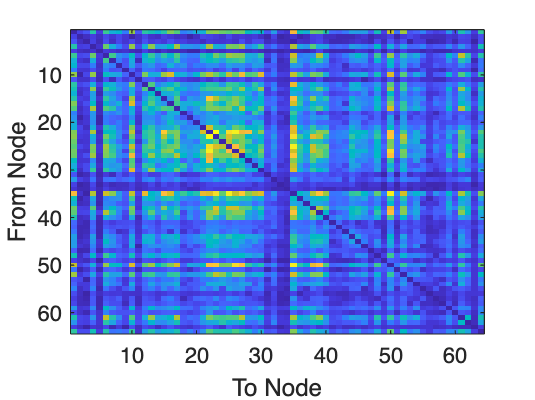

figure;imagesc(B);
xlabel('To Node');
ylabel('From Node');

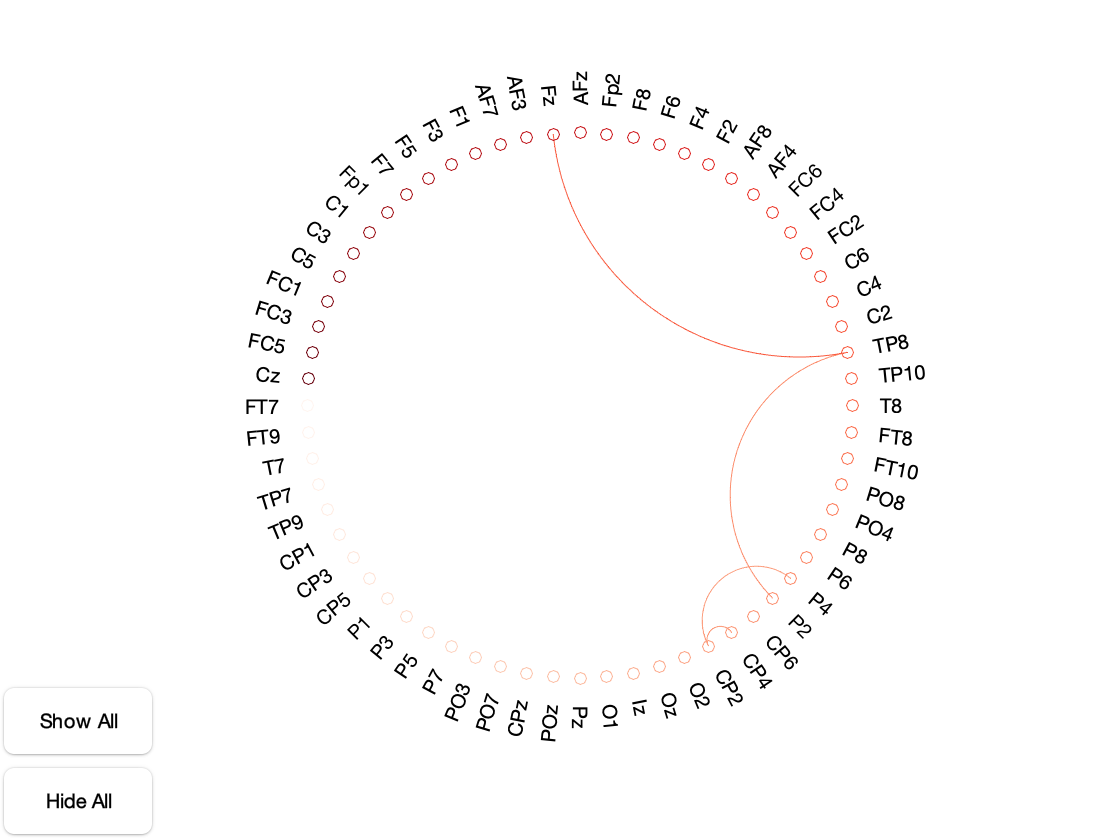


mask_increase = (B > 0);
increase = zeros(size(B));
increase(mask_increase) = B(mask_increase);
mask_decrease = (B < 0);
decrease = zeros(size(B));
decrease(mask_decrease) = B(mask_decrease);

% Circular plot
% Normalize for visualization
normalized_reorderedMatrix = abs(increase) / max(abs(increase(:))); % Normalize matrix values
normalized_reorderedMatrix_thresh = normalized_reorderedMatrix>0.9;
N = length(normalized_reorderedMatrix_thresh);
cmap = brewermap(N, 'Reds');
% Visualize with CircularGraph toolbox
figure; circularGraph(normalized_reorderedMatrix_thresh, 'Colormap', cmap, 'Label', reorderedLabels);

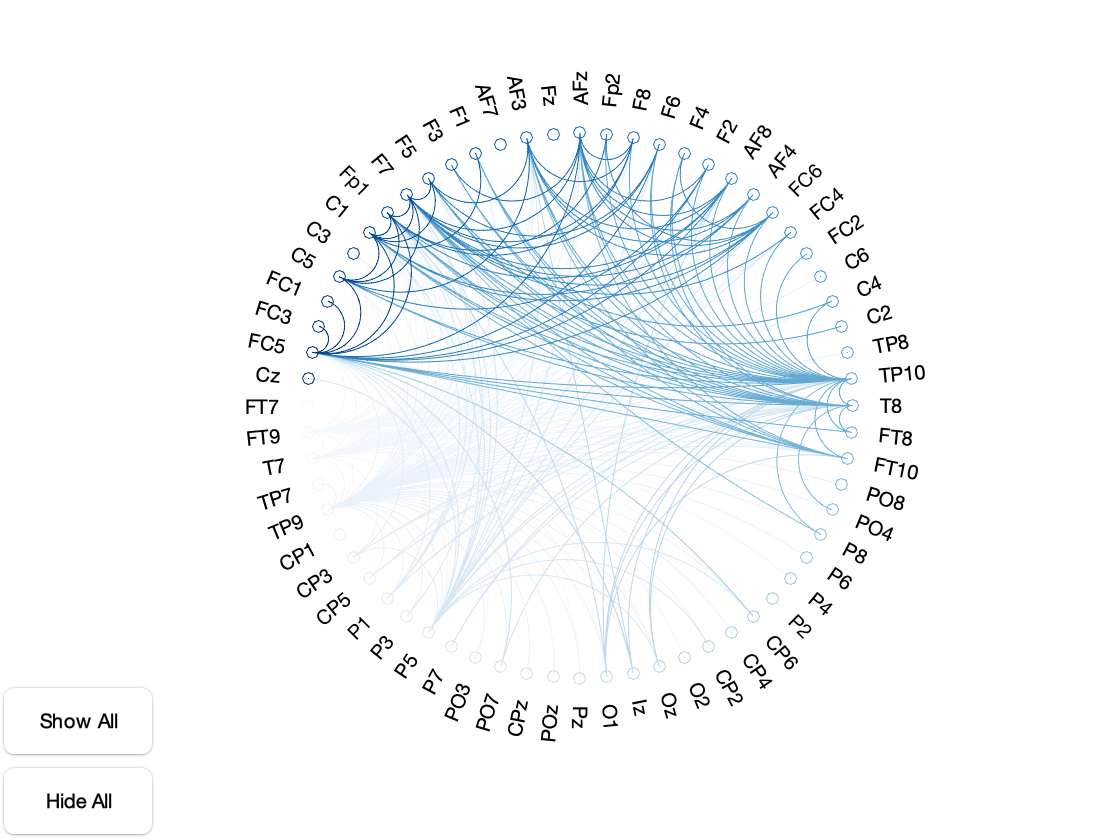

% figure; circularGraph(normalized_reorderedMatrix_thresh, 'Colormap', cmap,'Label', reorderedLabels);
% colorbar();

% Normalize for visualization
normalized_reorderedMatrix = abs(decrease) / max(abs(decrease(:))); % Normalize matrix values
normalized_reorderedMatrix_thresh = normalized_reorderedMatrix>0.9;
% Visualize with CircularGraph toolbox
N = length(normalized_reorderedMatrix_thresh);
cmap = brewermap(N, 'Blues');
figure; circularGraph(normalized_reorderedMatrix_thresh, 'Colormap', cmap, 'Label', reorderedLabels);

% figure; circularGraph(normalized_reorderedMatrix_thresh, 'Colormap', cmap,'Label', reorderedLabels);
% colorbar();

## STOP HERE FOR NOW

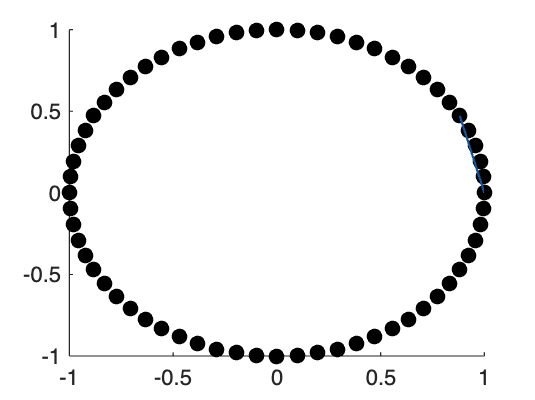

Index in position 1 exceeds array bounds. Index must not exceed 64.

% Example connectivity matrix (symmetric, 64x64 matrix)
% nChannels = 64;
% connectivity = rand(nChannels);  % Random weights (example)
% connectivity = triu(connectivity, 1); % Keep only upper triangle (no self-loops)
% connectivity = connectivity + connectivity'; % Symmetric matrix
connectivity = reorderedMatrix;
nodeLabels = reorderedLabels;
nChannels = 64;
% Normalize connectivity values for color mapping
minValue = min(connectivity(connectivity > 0)); % Minimum positive value
maxValue = max(connectivity(:));                % Maximum value
normalizedConnectivity = (connectivity - minValue) / (maxValue - minValue);

% Node positions in a circle
theta = linspace(0, 2*pi, nChannels + 1); % Angles for nodes (add first to close circle)
theta(end) = [];                          % Remove duplicate point
x = cos(theta);                           % X-coordinates
y = sin(theta);                           % Y-coordinates

% Define colormap
% cmap = jet(256); % Use 'jet' colormap (or 'parula', etc.)
cmap = brewermap(N, '-RdBu');

% Plot nodes in a circle
figure;
hold on;
scatter(x, y, 50, 'filled', 'k'); % Plot nodes as black circles

% Add edges (connections) with colors based on strength
for i = 1:nChannels
    for j = i+1:nChannels
        if connectivity(i, j) > 0 % Only plot edges with nonzero connectivity
            % Get normalized value and corresponding color
            colorIdx = round(normalizedConnectivity(i, j) * 255) + 1; % Scale to 1-256
            edgeColor = cmap(colorIdx, :); % Extract color from colormap

            % Plot the connection as a line
            line([x(i), x(j)], [y(i), y(j)], 'Color', edgeColor, 'LineWidth', 1);
        end
    end
end


% Add node labels
for i = 1:nChannels
    % Adjust label position slightly outward for better visibility
    text(x(i) * 1.1, y(i) * 1.1, nodeLabels{i}, 'HorizontalAlignment', 'center', ...
        'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');
end

% Add colorbar for connectivity strength
N = 256; % number of colorsdd
% cmap = [linspace(0,1,N).' linspace(0,1,N).' ones(N,1)]; % decreasing R and G; B = 1
cbh = colormap(cmap);
colorbar;
% colormap(cmap);
% colorbar('Ticks', [0 1], 'TickLabels', {num2str(minValue, '%.2f'), num2str(maxValue, '%.2f')});
% title('Circular Graph with Edge Colors Based on Connectivity Strength');
axis equal;
axis off;
hold off;


% Assume 'pre' and 'post' are your connectivity matrices of size (64, 64, n)
% 'n' is the number of participants

pre = fc_pre_group_all_chan;
post = fc_post_group_all_chan;
n = 17;

% Step 1: Z-transform each connectivity matrix (pre and post)
[rows, cols, n] = size(pre);
pre_z = zeros(rows, cols, n);
post_z = zeros(rows, cols, n);

for i = 1:rows
    for j = 1:cols
        % Z-transform for pre and post matrices for each electrode pair (i, j)
        pre_z(i, j, :) = (pre(i, j, :) - mean(pre(i, j, :), "omitnan")) / std(pre(i, j, :), "omitmissing");
        post_z(i, j, :) = (post(i, j, :) - mean(post(i, j, :), "omitnan")) / std(post(i, j, :), "omitmissing");
    end
end

% Step 2: Calculate the differences for each pair
diff = post_z - pre_z; % (64, 64, n) matrix of differences between pre and post

% Step 3: Perform paired t-test across participants for each electrode pair (i, j)
p_values = zeros(rows, cols); % To store p-values for each electrode pair
t_values = zeros(rows, cols);
for i = 1:rows
    for j = 1:cols
        
        % Perform a paired t-test for the difference between pre and post for this electrode pair
        [h, p, ci, stats] = ttest(squeeze(pre_z(i, j, :)), squeeze(post_z(i, j, :)));
        
        if p == NaN
            p_values(i, j) = NaN;
            t_values(i, j) = NaN;
        else
            p_values(i, j) = p;
            t_values(i, j) = stats.tstat;
        end
    end
end

% Step 4: Reshape p-values for FDR correction
% Flatten the p-values matrix into a vector for FDR correction
p_values_flat = p_values(:);

% Step 5: Apply FDR correction using mafdr
% 'p_values_flat' is the vector of p-values for all electrode pairs
q_values = mafdr(p_values_flat, 'BHFDR', true);  % FDR correction

% Reshape the corrected q-values back to a 64x64 matrix
q_values_matrix = reshape(q_values, rows, cols);
t_values_matrix = reshape(t_values, rows, cols);

% Step 6: Determine significant pairs based on FDR
alpha = 0.05;
significant_pairs = q_values_matrix < alpha;

% Display significant pairs
disp('Significant electrode pairs after FDR correction:');
disp(find(significant_pairs));

% Display result
disp('t_values_matrix');
figure;imagesc(t_values_matrix, [-1 1]);
xlabel('To Node');
ylabel('From Node');
% xticks(data_load.data_interp_avgref.label);
cbh = colorbar();

% TESTING FOR NORMALITY OF DATA --> SEEMS LIKE DATA IS NOT NORMAL ==> TTEST
% IS NOT VALID
% Assuming pre and post are your two connectivity matrices (64x64xn)
% Reshape the difference matrix to a vector (flatten the matrix if needed)
diff_vector = diff(:); 

% Create a Q-Q plot to visually inspect normality
qqplot(diff_vector);

% Create a histogram of the differences
figure;
histogram(diff_vector, 'Normalization', 'probability');
xlabel('Difference');
ylabel('Probability');
title('Histogram of Paired Differences');

% Kolmogorov-Smirnov test
[h, p] = kstest((diff_vector - mean(diff_vector, "omitnan")) / std(diff_vector, "omitmissing"));

% Display result
if h == 0
    disp('The data follows a normal distribution (p > 0.05)');
else
    disp('The data does not follow a normal distribution (p <= 0.05)');
end

% Lilliefors test for normality
[h, p] = lillietest(diff_vector);

% Display results
if h == 0
    disp('The data appears to be normally distributed (p > 0.05)');
else
    disp('The data does not appear to be normally distributed (p <= 0.05)');
end
